# Paper3: 1st test

How will a 4*8 binocular patch work?

## Setting up WS

CurrentFolder = pwd

CurrentFolder = '/Users/zhuochengxiao/Library/CloudStorage/OneDrive-Personal/Documents/GitHub/NYU-Vision-2Drive'

addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
SaveToFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper3PlotingData/']; % V1D2
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/25Function_Binocular/']; % V1D2
DataFolder1 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/16Function_Scheme/LARGE16/']; % V1D2
DataFolder2 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/25Function_binocular_realLGN/']; % V1D2
DataFolder4 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/Typical_trajs/']; % V1D2
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

addpath(DataFolder4)
addpath(SaveToFolder)
addpath(DataFolder2)
addpath(DataFolder1)
addpath(DataFolder)
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

### B1. Load LDE computations and do Fr distributions

Should rerun Sect 1 after in case loaded file contain any paths.

DataPt = 'V4D2'; %'V4D1'; 'V5D1'
load(sprintf("AllMFPixPara_Paper2TuneFig1%s.mat",DataPt))

CurrentFolder = pwd;
FigurePaperPath = [CurrentFolder '/Figures/Demo070124/']; % V1D2
MonocuFlag = false;
close all

## 2. Test for different x for E and I; yE and yI kept as 1 -- All killed are folded back

first get basic function information

Too time comsuming. --->> using HPC

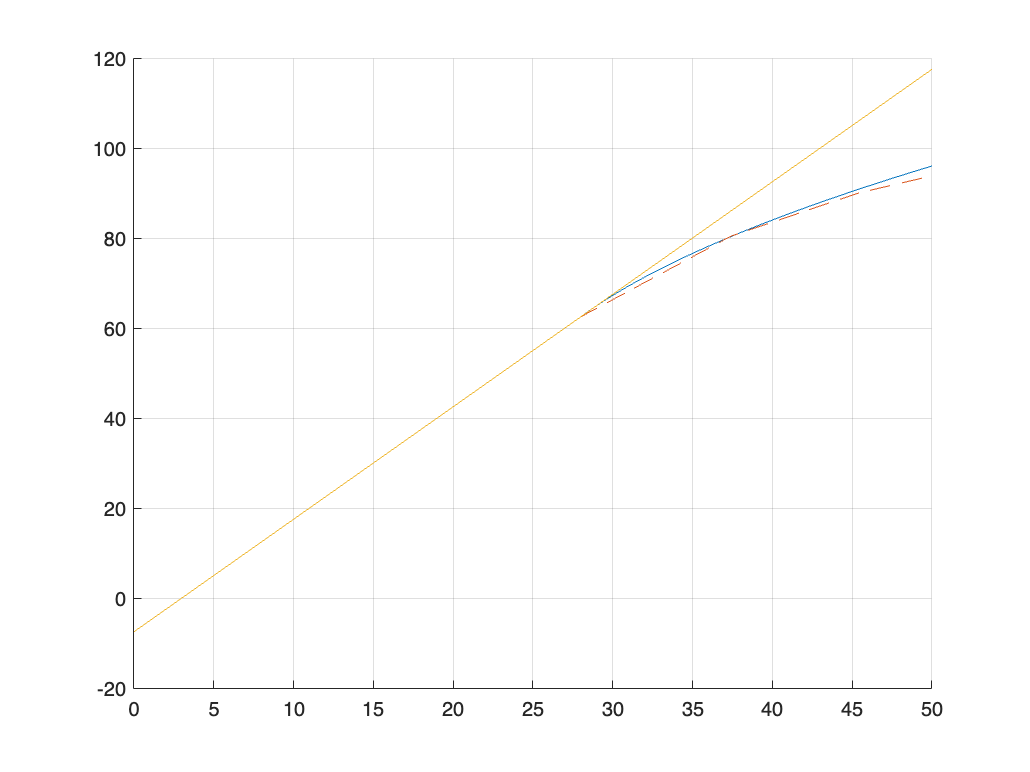

close all
xEAll = 0:0.2:1; xIAll = 0:0.2:1;
lgnSF = 2.5; lgnTF = 10;

ExpTex = 'CtrlL4';
Comment = ['L6Real' ExpTex];

L6pars = {};
%L6pars{2} = {2.5,3,[28; 31.5;37.4],[62.5; 69; 80.4],'quadratic'};
%L6pars{2} = {2.5,3,62.5,86,80.4,106,90};
L6pars{2} = {2.5,3,62.5,86,80.4,106,90,142.2, 102, 166.7, 108, 210, 118};
L6pars{1} = {2.5,3,[28; 40; 50],[62.5; 84; 96],'quadratic'};
xx = 0:0.1:50;
yy = L6Convert(xx, L6pars{1});
zz = L6Convert(xx, L6pars{2});
figure(99)
hold on
grid on
plot(xx,yy)
plot(xx,zz,'--')
plot(xx,2.5*(xx-3))

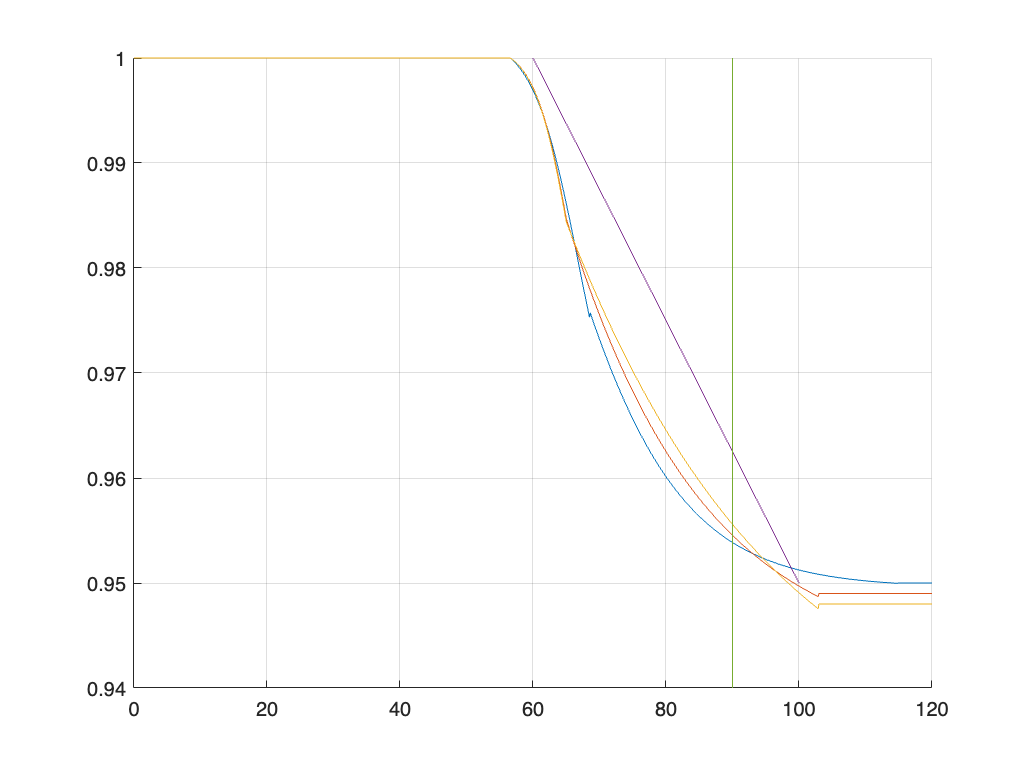


% Inhibition saturation info
IKp1.Thrsld1 = 56.6; IKp1.Thrsld2 = 68.6;
IKp1.Highist = 115;  IKp1.Slope = 0.95; % this is for new rule: multiplicative saturation
Isaturation = true;
IKp1.Mode = 'multisigmoid'; % or 'linear'
IKp1.IntaH = 5.5; IKp1.IntaL = -1;
IKp1.IntbL = 3; IKp1.IntbH = 0.5; % one side start from 3. another side start from 6

IKp3.Thrsld1 = 56.6; IKp3.Thrsld2 = 65;
IKp3.Highist = 103;  IKp3.Slope = 0.948; % this is for new rule: multiplicative saturation
IKp3.down1 = 0.3; % how much does the first part goes down -- a number between 0 and 1
Isaturation = true;
IKp3.Mode = 'multisigmoid'; % or 'linear'
IKp3.IntaH = 3.8; IKp3.IntaL = -2.5;
IKp3.IntbL = 3.4; IKp3.IntbH = -0.3; % one side start from 3. another side start from 6

IKp2.Thrsld1 = 56.6; IKp2.Thrsld2 = 65;
IKp2.Highist = 103;  IKp2.Slope = 0.949; % this is for new rule: multiplicative saturation
IKp2.down1 = 0.3; % how much does the first part goes down -- a number between 0 and 1
Isaturation = true;
IKp2.Mode = 'multisigmoid'; % or 'linear'
IKp2.IntaH = 4.5; IKp2.IntaL = -2.5;
IKp2.IntbL = 3.4; IKp2.IntbH = -0.3; % one side start from 3. another side start from 6

figure(100)
xx = 0:0.1:120;
[yy1,fac1] = InhMulp(xx,IKp1);
[yy2,fac2] = InhMulp(xx,IKp2);
[yy3,fac3] = InhMulp(xx,IKp3);
hold on
plot(xx,fac1)
plot(xx,fac2)
plot(xx,fac3)
plot(60:100,1-(0:40)*0.05/40)
yyz = 0.94:0.01:1;
plot(90*ones(size(yyz)),yyz)
grid on
axis([0 120 0.94 1])


IKpUse = IKp3;
EKpUse = {1,0,[50; 70; 100],[50; 60.5; 69],'quadratic'};

close all
%Comment = '';
for xEInd = 6%:length(xEAll)
    for xIInd = 6
        fprintf('xE=%.1f, xI=%.1f\n',xEAll(xEInd),xIAll(xIInd))
        for L6parId = 2
            fprintf('L6 ParameterID %d\n',L6parId)
            if L6pars{L6parId}{end} == 'quadratic'
                L6Comment = sprintf('%s',L6pars{L6parId}{end})
            else
                L6Comment = sprintf('linear')
            end
            tic
            %AngleList = {'0.0'}; % only vertical for now
            AngleList = {'0.0','7.5','15.0','22.5'};
            DomList =  {'Small','Large','LARGER'};

## 3. Set up initial conditions

            N_HCOutX = 4; N_HCOutY = 8; PixNumOut = N_HCOutX*N_HCOutY*NPixX*NPixY;
            N_HCinX = 4; N_HCinY = 4;
            NPixX = 10; NPixY = 10;

Parameters of L4 kernels

            AngleTestAll = 0:7.5:180; % 0:7.5:22.5; % has to be multiples of 7.5
            TestNum = length(AngleTestAll); ICTestAll = cell(TestNum,1);
            TestExSeq = xEAll(xEInd)*ones(size(0:7.5:180)); TestEySeq = 1*ones(size(TestExSeq));
            TestIxSeq = xIAll(xIInd)*ones(size(0:7.5:180)); TestIySeq = 1*ones(size(TestExSeq));

%%%60 deg: by rotating 15 deg pattern

Start from 90, then go to 22.5

            ICData = load(sprintf('LDETracesV4D2_NewSmear_ang0.0.mat'));
            load('LDETracesV4D2_NewSmear_ang0.0.mat')
            LDEICPart = ICData.LDEEquv;

            LDEICOut = HCRotXY(LDEICPart,0,N_HCinX,N_HCinY,N_HCOutX,N_HCOutY,NPixX,NPixY,0);
            for TestId = 1:TestNum
                ICTestAll{TestId} = LDEICOut;
            end
            LDEOutAll = cell(size(ICTestAll));
            NANFlag = false(size(ICTestAll));
            %BGFlagAllTest = cell(size(ICTestAll));

load equiv

            %PlotUse = load([DataFolder2 sprintf('LDETraces_bg-ang%s.mat',AngPrint)],'LDEEquv');
            %LDEEquv = PlotUse.LDEEquv;
            %LDEEquv = HCRot(LDEEquv,RotInd,N_HCOut,NPixX,NPixY,MirInd);

Hyperparameters of iterations

            p = 0.33;% 1-p for the original input
            EpocTest = 150;
            ExportFlag = 'xn';

            L2Diff_OneStepAll = zeros(length(ICTestAll),EpocTest+1);
            DiffVecAll = zeros(length(ICTestAll),EpocTest+1,3*NPixY*NPixX);

Since we are doing different network architectures now - need to separate inputs to the S C I functions!!!

            % Determine L4 Input from a range
            L4SE = zeros(N_HC*NPixX*N_HC*NPixY,1);
            L4SI = zeros(N_HC*NPixX*N_HC*NPixY,1);
            L4CE = zeros(N_HC*NPixX*N_HC*NPixY,1);
            L4CI = zeros(N_HC*NPixX*N_HC*NPixY,1);
            L4IE = zeros(N_HC*NPixX*N_HC*NPixY,1);
            L4II = zeros(N_HC*NPixX*N_HC*NPixY,1);
            for PInd = 1:N_HC*NPixX*N_HC*NPixY
                L4SE(PInd) = (C_SS_Pixel_Us(PInd,:)*FrSPixVec          + C_SC_Pixel_Us(PInd,:)*FrCPixVec);
                L4SI(PInd) =  C_SI_Pixel_Us(PInd,:)*FrIPixVec ;
                L4CE(PInd) = (C_CS_Pixel_Us(PInd,:)*FrSPixVec          + C_CC_Pixel_Us(PInd,:)*FrCPixVec);
                L4CI(PInd) =  C_CI_Pixel_Us(PInd,:)*FrIPixVec ;
                L4IE(PInd) = (C_IS_Pixel_Us(PInd,:)*FrSPixVec          + C_IC_Pixel_Us(PInd,:)*FrCPixVec);
                L4II(PInd) =  C_II_Pixel_Us(PInd,:)*FrIPixVec ;
            end
            L4Eall = L4SE+L4CE+L4IE; L4Iall = L4SI+L4CI+L4II;
            L4SEp = mean(L4SE./L4Eall);L4CEp = mean(L4CE./L4Eall);L4IEp = mean(L4IE./L4Eall);
            L4SIp = mean(L4SI./L4Iall);L4CIp = mean(L4CI./L4Iall);L4IIp = mean(L4II./L4Iall);

## Compute NESSs for each angle

            for TestId = 1:TestNum
                AngleInpt = AngleTestAll(TestId);

                RotInd = floor(AngleInpt/45); % 0-3
                MirInd = mod(floor(AngleInpt/22.5),2); % 0: no mirror; 1: mirror
                switch MirInd % find the corresponding source
                    case 0
                        AngSource = mod(AngleInpt,45);
                    case 1
                        AngSource = mod(-AngleInpt,45);
                end

                % Use the source, decide which response function for angle should I use
                AngFuncCtgrCdid = 0:7.5:22.5;
                [~,AngFuncCtgr] = min(abs(AngFuncCtgrCdid - AngSource));

                AngPrint = AngleList{AngFuncCtgr};
                Angle = str2num(AngPrint); % can select from 0 7.5 15 22.5

load all precomputed domains

                L4EmeshXAll = cell(size(DomList));
                L4ImeshYAll = cell(size(DomList));
                LDEFrfuncAll = cell(size(DomList));
                for DomInd = 1:length(DomList)
                    FuncTemp = load(sprintf('Func135%s-%s-Ang%s-SF%.1fTF%d-%s.mat',...
                        DataPt,Comment,AngPrint,lgnSF,lgnTF,DomList{DomInd}),...
                        'LDEFrfunc','L4EmeshX','L4ImeshY');
                    L4EmeshXAll{DomInd} = FuncTemp.L4EmeshX;
                    L4ImeshYAll{DomInd} = FuncTemp.L4ImeshY;
                    LDEFrfuncAll{DomInd} = FuncTemp.LDEFrfunc;
                end

## 4. Iteration 

New: Need to extend all these to arbitrary HC numbers!

                %    N_HCOut = 4; PixNumOut = N_HCOut^2*NPixX*NPixY;
                LGNlist = 5; L6list = 33;
                OD_SMapModi = OD_SMap;

Needs to replace the midel row as "5" -- Background

                %OD_SMapModi = OD_SMap(1:2*n_S_HC,1:2*n_S_HC);
                if MonocuFlag
                    OD_SMapModi(n_S_HC+1:2*n_S_HC,1:end) = 5;
                    SaveStr = ['Mono' Comment];
                else
                    SaveStr = ['Bino' Comment];
                end

L6 kernel

                L6ConvSig = 0.75;
                L6ConvTruc = 1.5/(L6ConvSig);
                Kersize = floor(2*L6ConvSig*L6ConvTruc);
                if Kersize<=0
                    Kersize= 2; % at least 1
                end
                [x,y] = meshgrid(1:Kersize,1:Kersize);
                c = Kersize/2;
                exponent = ((x-c).^2+(y-c).^2)/(2*L6ConvSig^2);
                L6Kernel = exp(-exponent);
                L6Kernel(L6Kernel<exp(-(L6ConvTruc*1.0)^2/2))=0; % truncate
                L6Kernel = L6Kernel + ...
                    L6Kernel(end:-1:1,:) + ...
                    L6Kernel(:,end:-1:1) + ...
                    L6Kernel(end:-1:1,end:-1:1);%symmetrize
                L6Kernel = L6Kernel/sum(L6Kernel,'all'); % normalize
                L6Kernel = L6Kernel/((sum(L6Kernel,'all') - L6Kernel(2,2))/(1-0.3));
                L6Kernel(2,2) = 0.3;

LGN and L6 are blurred 

                N_HCs = 3; % shrink to 2*2
                FigOn = false;
                LGNsmear = n_S_HC*0.2;
                TruncLGN = 1;
                LGNFilt_Grating = SpatialGaussianFilt_my(OD_SMapModi,...
                    N_HCs,n_S_HC,LGNsmear,TruncLGN,FigOn);

                if ~MonocuFlag
                    LGNFilt_Grating = [LGNFilt_Grating,zeros(size(LGNFilt_Grating,1),1)];
                end

                PixLGNCtgr = LGNIndSpat_Rec(...
                    LGNFilt_Grating,1:LGNlist,NnSPixel,N_HC,N_HCOutX,N_HCOutY,NPixX,NPixY,true);

                % symmetrize !! This is actually trick, so I do it ad hoc
                PixLGNCtgr = Ocu_LGNL6symm(PixLGNCtgr,N_HCOutX,N_HCOutY,NPixX,NPixY);

completely BG or not?

                BGFlag = false;
                if BGFlag
                    PixL6Ctgr(:,end) = 1; PixL6Ctgr(:,1:end-1) = 0;
                    PixLGNCtgr(:,end) = 1; PixLGNCtgr(:,1:end-1) = 0;
                end

However, the Ctgr for pixels needs to be rotated/flipped to represent the actual gratings

**Instead of rotating existing ctgr fields, I should simply permute 1234  **

                MirInd = logical(MirInd);
                CtgrOrder = [2,1;3,4]; % for lower left HC
                CtgrOrderUse = rot90(CtgrOrder,RotInd);
                if MirInd
                    %flipDim = mod(RotInd,2)+1; %1 for col 2 ofr row
                    CtgrOrderUse = flip(CtgrOrderUse,1);
                end
                CtgrOrderReadout = ...
                    [CtgrOrderUse(1,2);
                    CtgrOrderUse(1,1);
                    CtgrOrderUse(2,1);
                    CtgrOrderUse(2,2)];
                %    for Ctgr = 1:4
                %         PixL6Ctgr(:,Ctgr) = ...
                %             HCRot_Rec(PixL6Ctgr(:,Ctgr),RotInd,N_HCOutX,N_HCOutY,NPixX,NPixY,MirInd);
                %         PixLGNCtgr(:,Ctgr) = ...
                %             HCRot_Rec(PixLGNCtgr(:,Ctgr),RotInd,N_HCOutX,N_HCOutY,NPixX,NPixY,MirInd);
                %    end

                % let's implement something cheap now for 45 deg
                PixLGNCtgr = PixLGNCtgr(:,[CtgrOrderReadout',5]);

Get pixelwise connectivities

NOTE: NEED to modify AveSpatKer_Rec to implement the ocular modulation of connectivity kernels    

                ParaEx = TestExSeq(TestId); ParaEy = TestEySeq(TestId);
                ParaIx = TestIxSeq(TestId); ParaIy = TestIySeq(TestId);

                C_SS_mean = sparse(AveSpatKer_Rec(C_SS_Pixel_Us,N_HC,...
                    N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
                C_CS_mean = sparse(AveSpatKer_Rec(C_CS_Pixel_Us,N_HC,...
                    N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
                C_IS_mean = sparse(AveSpatKer_Rec(C_IS_Pixel_Us,N_HC,...
                    N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
                C_SC_mean = sparse(AveSpatKer_Rec(C_SC_Pixel_Us,N_HC,...
                    N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
                C_CC_mean = sparse(AveSpatKer_Rec(C_CC_Pixel_Us,N_HC,...
                    N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
                C_IC_mean = sparse(AveSpatKer_Rec(C_IC_Pixel_Us,N_HC,...
                    N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
                C_SI_mean = sparse(AveSpatKer_Rec(C_SI_Pixel_Us,N_HC,...
                    N_HCOutX,N_HCOutY,NPixX,NPixY,ParaIx,ParaIy));
                C_CI_mean = sparse(AveSpatKer_Rec(C_CI_Pixel_Us,N_HC,...
                    N_HCOutX,N_HCOutY,NPixX,NPixY,ParaIx,ParaIy));
                C_II_mean = sparse(AveSpatKer_Rec(C_II_Pixel_Us,N_HC,...
                    N_HCOutX,N_HCOutY,NPixX,NPixY,ParaIx,ParaIy));

                Conn_Reduc_TestS = 6; Conn_Reduc_TestC = 4;
                Reduc_S = Conn_Reduc_TestS*(1-CplxR); Reduc_C = Conn_Reduc_TestC*CplxR;
                P_SS_rate = (N_SS-Reduc_S)/N_SS; C_SS_meanU = C_SS_mean * P_SS_rate;
                P_SC_rate = (N_SC-Reduc_C)/N_SC; C_SC_meanU = C_SC_mean * P_SC_rate;
                P_CS_rate = (N_CS-Reduc_S)/N_CS; C_CS_meanU = C_CS_mean * P_CS_rate;
                P_CC_rate = (N_CC-Reduc_C)/N_CC; C_CC_meanU = C_CC_mean * P_CC_rate;

Firing rate suppresion

                %     EKp.Thrsld = 50; EKp.Highist = [200,150]; EKp.HardBound = 200; EKp.Slope = 0;
                %
                %     IKp.Thrsld = 70; IKp.Highist = [100,95];  IKp.HardBound = 120; IKp.Slope = 1; % 1; 0.9(95); 0.8(9)

set up IC

                tic
                ICUse = ICTestAll{TestId}; %
                IniTest = ICUse;
                %IniTest.S = symmHCs(ICUse.S,N_HCOut,NPixX,NPixY);
                %IniTest.C = symmHCs(ICUse.C,N_HCOut,NPixX,NPixY);
                %IniTest.I = symmHCs(ICUse.I,N_HCOut,NPixX,NPixY);


start iteration

                [LDEOutAll{TestId},LDEIL2Diff{TestId},L2DiffNormNeib{TestId},~,~,FuncUse,...
                    NANFlag(TestId)] = ...
                    LDEIteration_135FuncMain_CombDom_RealLGNL6(...
                    PixLGNCtgr,L6Kernel,IniTest,p,L6pars{L6parId}, EpocTest,...
                    C_SS_meanU,C_CS_meanU,C_IS_mean,...
                    C_SC_meanU,C_CC_meanU,C_IC_mean,...
                    C_SI_mean, C_CI_mean, C_II_mean,...
                    L4SEp, L4SIp, ...
                    L4CEp, L4CIp, ...
                    L4IEp, L4IIp, ...
                    L4EmeshXAll,L4ImeshYAll,LDEFrfuncAll,...
                    N_HCOutY,NPixX,NPixY,Isaturation,'xn',EKpUse,IKpUse)  ;
                LDEEquv = LDEOutAll{TestId}{end};

                RunTime = toc;
                sprintf('RunTime = %.2f',RunTime)

                if ~NANFlag(TestId)
                    for EpcInd = 1:EpocTest+1
                        LDEPertRslt = LDEOutAll{TestId}{EpcInd};
                        SDiff = LDEPertRslt.S - LDEEquv.S;
                        SDiffHC = reshape(SDiff,N_HCOutY*NPixY,N_HCOutX*NPixX);
                        SDiff = reshape(SDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);
                        CDiff = LDEPertRslt.C - LDEEquv.C;
                        CDiffHC = reshape(CDiff,N_HCOutY*NPixY,N_HCOutX*NPixX);
                        CDiff = reshape(CDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);
                        IDiff = LDEPertRslt.I - LDEEquv.I;
                        IDiffHC = reshape(IDiff,N_HCOutY*NPixY,N_HCOutX*NPixX);
                        IDiff = reshape(IDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);

                        L2Diff_OneStepAll(TestId,EpcInd) = ...
                            sqrt(sum((SDiff*(1-CplxR)+CDiff*CplxR).^2,'all'));%sqrt(sum([SDiff;CDiff;IDiff].^2));
                        DiffVecAll(TestId,EpcInd,:) = [SDiff;CDiff;IDiff];
                    end
                end
            end

   Comment below if don't need to save data (usually for setting up new NESSs) 

            SaveStrUse = sprintf('%s_RealLGNSF%.1fTF%d-L6Real%s_L4Idepprl%.1fm%.1fh%.1f-Sd%.1fCd%.1f',...
    SaveStr,lgnSF,lgnTF, L6Comment, IKpUse.Thrsld1,IKpUse.Thrsld2, IKpUse.Highist,Conn_Reduc_TestS,Conn_Reduc_TestC);

            save([SaveToFolder sprintf('RealLGN-NESSs-ModiIdep_%s.mat',SaveStrUse)],...
                'LDEOutAll','LDEIL2Diff','L2DiffNormNeib','L2Diff_OneStepAll','DiffVecAll','TestExSeq','TestExSeq','AngleTestAll','L6pars')
            RunTime = toc;
            fprintf('RunTime = %.2f',RunTime)
        end

    end
end

xE=1.0, xI=1.0


L6 ParameterID 2


L6Comment = 'linear'

ans = 'RunTime = 42.67'

ans = 'RunTime = 42.43'

ans = 'RunTime = 42.48'

ans = 'RunTime = 42.48'

ans = 'RunTime = 42.21'

ans = 'RunTime = 44.59'

ans = 'RunTime = 44.56'

ans = 'RunTime = 42.30'

ans = 'RunTime = 42.61'

ans = 'RunTime = 43.36'

ans = 'RunTime = 43.93'

ans = 'RunTime = 43.40'

ans = 'RunTime = 42.74'

ans = 'RunTime = 43.24'

ans = 'RunTime = 42.66'

ans = 'RunTime = 44.27'

ans = 'RunTime = 43.28'

ans = 'RunTime = 43.46'

ans = 'RunTime = 43.54'

ans = 'RunTime = 43.75'

ans = 'RunTime = 43.81'

ans = 'RunTime = 43.44'

ans = 'RunTime = 43.42'

ans = 'RunTime = 43.28'

ans = 'RunTime = 43.45'

RunTime = 47.73

## FrE  for all XY tests; fixing grating angle

close all
MonocuFlag = false;
if MonocuFlag
    SaveStr = ['Mono' Comment];
else
    SaveStr = ['Bino' Comment];
end

L6parId = 2;
%IKpUse = IKp3;

if L6pars{L6parId}{end} == 'quadratic'
    L6Comment = sprintf('%s',L6pars{L6parId}{end})
else
    L6Comment = sprintf('linear')
end

L6Comment = 'linear'



DataStrUse = sprintf('%s_RealLGNSF%.1fTF%d-L6Real%s_L4Idepprl%.1fm%.1fh%.1f-Sd%.1fCd%.1f',...
    SaveStr,lgnSF,lgnTF, L6Comment, IKpUse.Thrsld1,IKpUse.Thrsld2, IKpUse.Highist,Conn_Reduc_TestS,Conn_Reduc_TestC);


load([SaveToFolder sprintf('RealLGN-NESSs-ModiIdep_%s.mat',SaveStrUse)],...
    'LDEOutAll','L2Diff_OneStepAll','DiffVecAll','AngleTestAll')

Fig3 = figure("Name",sprintf('NESSs_%s',DataStrUse),...
    'units','normalized','outerposition',[0,0,0.5,1]);
ha = tight_subplot(5,5,[.04 .015],[.05 .05],[.05 .1]);
for TestId = 1:TestNum
    if NANFlag(TestId)
        continue
    end
    axes(ha(TestId));
    ShowField_Rec(...
        LDEOutAll{TestId}{end}.S*(1-CplxR)+LDEOutAll{TestId}{end}.C*CplxR,...
        ...%LDEOutAll{TestId}{end}.I,...
        1:PixNumOut,N_HCOutX*NPixX,N_HCOutY*NPixY)
    title(sprintf('%.1f',AngleTestAll(TestId)),...
        'Interpreter','tex')
    axes(ha(TestId));
    axis([0.5 20.5 10.5 30.5])
    axis square
    caxis([3 40]);
    colorbar off
    if mod(TestId,5) == 0
        Pos1 = get(gca,'Position');
        cbr1 = colorbar(gca, 'Position', [Pos1(1)+Pos1(3)+0.04  Pos1(2)  0.01  Pos1(4)]);
        set(cbr1,'FontSize',13)
    end

end

Save and Print Figs

FigName1 = sprintf('NESSs-ModiIDep_%s',DataStrUse);
savefig(Fig3,[FigurePaperPath FigName1 '.fig']);

Fig3.PaperUnits = 'centimeters';
Fig3.PaperSize = [36,28];
Fig3.PaperOrientation = "landscape";
exportgraphics(Fig3,[FigurePaperPath FigName1 '.pdf'],'Resolution',150)
close all

## 4. Make Tuning curves

close all
MonocuFlag = false;
if MonocuFlag
    SaveStr = ['Mono' Comment];
else
    SaveStr = ['Bino' Comment];
end


DataStrUse = sprintf('%s_RealLGNSF%.1fTF%d-L6Real%s_L4Idepprl%.1fm%.1fh%.1f-Sd%.1fCd%.1f',...
    SaveStr,lgnSF,lgnTF, L6Comment, IKpUse.Thrsld1,IKpUse.Thrsld2, IKpUse.Highist,Conn_Reduc_TestS,Conn_Reduc_TestC);


load([SaveToFolder sprintf('RealLGN-NESSs-ModiIdep_%s.mat',SaveStrUse)],...
    'LDEOutAll','L2Diff_OneStepAll','DiffVecAll','AngleTestAll')

[xAll,yAll] = meshgrid(1:10,1:10);

if MonocuFlag
    TCDriveFlagAll = [true,false];
else
    TCDriveFlagAll = true;
end

for TCDriveFlag = TCDriveFlagAll
    if TCDriveFlag
        CtgrPix = ...
            [10,5
            10,3;
            %10,2;
            %10,1;
            9,2;
            %9,1;
            8,1;
            6,1];
        ODStr = 'Dr';
    else
        CtgrPix = ...
            [10,16
            10,18;
            %10,19;
            %10,20;
            9,19;
            %9,20;
            8,20;
            6,20];
        ODStr = 'NoDr';
    end
    TuningCurvePlotAll = cell(length(CtgrPix),1);
    % Do the 2*2 HC and print pixel texts
    Fig5D = figure('Name','TuningCurves','units','normalized',...
        'outerposition',[0,0,1,0.5]);
    HCPlot = subplot(1,3,1);
    Patt = LDEOutAll{1}{end};
    EPatt = Patt.S*(1-CplxR) + Patt.C*CplxR;

            Print constritions only when binocular

    if ~MonocuFlag
        SMap = reshape(Patt.S,N_HCOutY*NPixY,N_HCOutX*NPixX);
        CMap = reshape(Patt.C,N_HCOutY*NPixY,N_HCOutX*NPixX);
        EMap = reshape(EPatt, N_HCOutY*NPixY,N_HCOutX*NPixX);
        IMap = reshape(Patt.I,N_HCOutY*NPixY,N_HCOutX*NPixX);
        optY = floor(NPixY/2); optX = NPixX;
        ortY = floor(NPixY/2); ortX = 1;
        Eopt = EMap(optY,optX); Eort = EMap(ortY,ortX);
        Sopt = SMap(optY,optX); Sort = SMap(ortY,ortX);
        Copt = CMap(optY,optX); Cort = CMap(ortY,ortX);
        Iopt = IMap(optY,optX); Iort = IMap(ortY,ortX);
        fprintf(['Eopt=%.1fHz; Copt/Sopt=%.1f; Iopt/Eopt=%.1f; Eort=%.1fHz\n',...
            'Eort=%.1fHz; Cort/Sort=%.1f; Iort/Eort=%.1f; Eopt/Eort=%.1f'],...
            Eopt,        Copt/Sopt,      Iopt/Eopt,      Eort,...
            Eort,        Cort/Sort,      Iort/Eort,      Eopt/Eort)
    end

          make fig panels  

    ShowField_Rec(EPatt, 1:PixNumOut,NPixY*N_HCOutX,NPixX*N_HCOutY)
    if TCDriveFlag
        axis([0.5 10.5 0.5 10.5])
    else
        axis([0.5 10.5 10.5 20.5])
    end
    axis square
    caxis([3 37])

    hold on
    PixTxt = 'a':char('a'+length(CtgrPix)-1); % Text on the pixel
    MarkerList = {'*','o','+','x','s','^','p'};
    LW = [2,1/2,2,1/2,2,1/2,2];

    for PixInd = 1:length(CtgrPix)
        clear text
        x = CtgrPix(PixInd,1); y = CtgrPix(PixInd,2);
        txt = text(x-0.3, y+0.1, PixTxt(PixInd),...
            'FontSize',22,'FontWeight','bold');
        if PixInd == 1
            txt.Color = [1,1,1];
        end
    end

Tuning curves

    TCPlot = subplot(1,3,[2,3]);
    hold on
    AnglePlot = [AngleTestAll(floor(end/2)+1:end-1),...
        AngleTestAll(1:floor(end/2)), ...
        AngleTestAll(floor(end/2)+1)];
    AngleUnique = 1:length(AnglePlot);
    for PixInd = 1:length(CtgrPix)
        x = CtgrPix(PixInd,1); y = CtgrPix(PixInd,2);
        TuningCurve = zeros(size(AngleTestAll));
        for angId = 1:length(TuningCurve)
            PattS = LDEOutAll{angId}{end}.S;
            PattS = reshape(PattS,NPixY*N_HCOutY,NPixX*N_HCOutX);
            PattC = LDEOutAll{angId}{end}.C;
            PattC = reshape(PattC,NPixY*N_HCOutY,NPixX*N_HCOutX);
            TuningCurve(angId) = ...
                PattS(y,x) * (1-CplxR) + ...
                PattC(y,x) * CplxR;
        end
        TuningCurvePlot = ...
            [TuningCurve(floor(end/2)+1:end-1),...
            TuningCurve(1:floor(end/2)), ...
            TuningCurve(floor(end/2)+1)];
        plot(AngleUnique,TuningCurvePlot,'k','LineWidth',LW(PixInd),...)
            ...% 'Color',TunCurColor,
            'DisplayName',PixTxt(PixInd),'Marker',MarkerList{PixInd},...
            'MarkerSize',18)
        TuningCurvePlotAll{PixInd} = TuningCurvePlot;
    end

    plot(AngleUnique,3*ones(size(AngleUnique)),'r','LineWidth',LW(1),'DisplayName','BG')

    xtickAng = AnglePlot;
    xtickLab = cell(size(xtickAng));
    for xticInd = 1:length(xtickAng)
        if mod(xticInd,4) == 1
            xtickLab{xticInd} = num2str(xtickAng(xticInd));
        end
    end

    set(TCPlot,'FontSize',10)
    xlabel('Grating Angle (deg)','FontSize',16);
    ylabel('E firing rate','FontSize',16)
    title('Tuning Curves of Pixels','FontSize',16)

    xlim([1 25])
    ylim([2 37]);
    set(gca,'xtick',AngleUnique,'xticklabel',xtickLab)
    %set(gca, 'FontSize',14)
    grid on
    legend('Location','northwest','FontSize',16)

    Fig5E = figure('Name','TuningCurves','units','normalized',...
        'outerposition',[0,0,0.5,1]);
    for PixInd = 1:3
        subplot(3,1,PixInd)
        hold on
        grid on
        xlabel('Grating Angle (deg)','FontSize',16);
        ylabel('E firing rate','FontSize',16)
        xlim([1 25])
        ylim([2 37]);
        set(gca,'xtick',AngleUnique,'xticklabel',xtickLab)
        x = CtgrPix(PixInd,1); y = CtgrPix(PixInd,2);
        TuningCurve = zeros(size(AngleTestAll));
        for angId = 1:length(TuningCurve)
            PattS = LDEOutAll{angId}{end}.S;
            PattS = reshape(PattS,NPixY*N_HCOutY,NPixX*N_HCOutX);
            PattC = LDEOutAll{angId}{end}.C;
            PattC = reshape(PattC,NPixY*N_HCOutY,NPixX*N_HCOutX);
            TuningCurve(angId) = ...
                PattS(y,x) * (1-CplxR) + ...
                PattC(y,x) * CplxR;
        end
        TuningCurvePlot = ...
            [TuningCurve(floor(end/2)+1:end-1),...
            TuningCurve(1:floor(end/2)), ...
            TuningCurve(floor(end/2)+1)];
        plot(AngleUnique,TuningCurvePlot,'k','LineWidth',LW(PixInd),...)
            ...% 'Color',TunCurColor,
            'DisplayName',PixTxt(PixInd),'Marker',MarkerList{PixInd},...
            'MarkerSize',18)
        TuningCurvePlotAll{PixInd} = TuningCurvePlot;
        
        height32 = (max(TuningCurvePlot,[],'all')-3)*2/3 + 3;
        plot(AngleUnique,height32 * ones(size(AngleUnique)))
        
        % circular variance
        xdata_degrees = -90:7.5:90; % xdata in degrees
        ydata = TuningCurvePlot;    % ydata representing the tuning curve

        % Convert xdata to radians
        xdata_radians = deg2rad(2*xdata_degrees(1:end-1));

        % Compute the resultant vector length
        R = sum(ydata(1:end-1) .* exp(1i * xdata_radians)) / sum(ydata(1:end-1));

        % Compute the circular variance
        circ_variance = 1 - abs(R);
        intersection_points = findintersection(xdata_degrees,TuningCurvePlot,height32)
        BW = intersection_points(2,1) - intersection_points(1,1);

        title(sprintf('CV = %.2f, BW = %.1f',circ_variance,BW),...
            'FontSize',16)
    end

Save figures

    FigName1 = sprintf('TC-ModiIdep_%s-%s',ODStr,DataStrUse);
    savefig(Fig5D,[FigurePaperPath FigName1 '.fig']);

    FigName2 = sprintf('TC-ModiIdep-sepa_%s-%s',ODStr,DataStrUse);
    savefig(Fig5E,[FigurePaperPath FigName2 '.fig']);


Print Figs

    Fig5D.PaperUnits = 'centimeters';
    Fig5D.PaperSize = [36,28];
    Fig5D.PaperOrientation = "landscape";
    exportgraphics(Fig5D,[FigurePaperPath FigName1 '.pdf'],'Resolution',150)

    Fig5E.PaperUnits = 'centimeters';
    Fig5E.PaperSize = [36,28];
    Fig5E.PaperOrientation = "landscape";
    exportgraphics(Fig5E,[FigurePaperPath FigName2 '.pdf'],'Resolution',150)
    close all
end

Eopt=33.5Hz; Copt/Sopt=5.1; Iopt/Eopt=2.7; Eort=2.9Hz
Eort=2.9Hz; Cort/Sort=1.4; Iort/Eort=6.1; Eopt/Eort=11.4

intersection_points =   -20.3948   23.3266
   22.4131   23.3266


intersection_points =   -14.1056   22.0996
   32.0082   22.0996


intersection_points =    -4.5572   20.1908
   49.5154   20.1908


% end